# Régulation de Température d'un procédé Thermique

 Caractéristique statique du système pour une vitesse du ventilateur de 6V

V0_vent = 6;
Uo_vent = 5;
Yo_vent = 3.2;

Fonction de Transfert

ts = 2;
s = tf('s');
z = tf('z', ts);
k1 = 0.6;
k2 = -0.25;
tau = 5;

H = 1/(1+tau*s)^2


H =
 
          1
  -----------------
  25 s^2 + 10 s + 1
 
Continuous-time transfer function.



Compensation Pôles/Zéros:  dans ce méthode il faut égaliser le numérateur du correcteur avec le dénominateur de la fonction de transfert. On trouve: 

Ti = 2*tau;
Td = (tau^2)/Ti;

Donc sans tenir compte de la perturbation, on peut trouve comme Boucle Fermé:

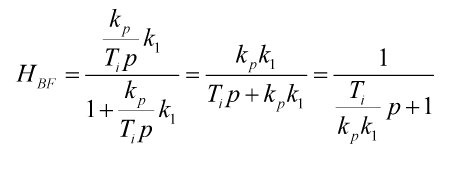

Nous savons aussi qui le temp désiré est tdes = 3*tau, et tau = Ti/(kp*ki), donc:

kp = 4;
alfa = 100*Td

alfa = 250

C = kp*( 1 + 1/(Ti*s) + (Td*s)/(1+(Td/alfa)*s) )


C =
 
  100.4 s^2 + 40.04 s + 4
  -----------------------
      0.1 s^2 + 10 s
 
Continuous-time transfer function.



Discretization 

H2 = 1/(1+tau*s)^2


H2 =
 
          1
  -----------------
  25 s^2 + 10 s + 1
 
Continuous-time transfer function.



H1 = tf([1], [tau^2 2*tau 1])


H1 =
 
          1
  -----------------
  25 s^2 + 10 s + 1
 
Continuous-time transfer function.



Hd = c2d(H1,ts,'zoh')


Hd =
 
   0.06155 z + 0.04714
  ----------------------
  z^2 - 1.341 z + 0.4493
 
Sample time: 2 seconds
Discrete-time transfer function.




%G = ((1 - exp(-ts*(1/tau))*(1 + ts*(1/tau)))*z + exp(-ts*(1/tau))*(ts*(1/tau) - 1 + exp(-ts*(1/tau))))/(z - exp(-ts*(1/tau)))^2


G =
 
   0.06155 z + 0.04714
  ----------------------
  z^2 - 1.341 z + 0.4493
 
Sample time: 2 seconds
Discrete-time transfer function.



%Hpiv = tf(Kpv) + tf(Kiv, [1 0]);